clear all 
close all

We set the solver tolerance 

% ODE_TOL  = 1e-10;
% DIFF_INC = sqrt(ODE_TOL);


The LHS matrix will sample each parameter over the range of uncertainty with corresponding distribution which is defined by 

%Parameter_settings_EFAST_Marino

% runs=3;
% k = size(pmax,1); 
% LHSmatrix = zeros(runs, k); 
% 
% for i =1 : k 
%     LHSmatrix(:,i) = LHS_Call(pmin(i),...
%  baseline(i), pmax(i), 0 ,runs,'unif');
% end 


The matrix will be saved as a csv file to be used later. 

%csvwrite('LHS.csv', LHSmatrix); %save LHS matrix


When needing to use the matrix, we can call the LHS matrix 

% load parameter set generated by latin hypercube sampling
%parset = dlmread('psets_fullrange');
%parset = dlmread('LHS.csv');


We will then calculate the sensitivity matrix. For each parameter $x_i$, a local sensitivity measure is calculated based on the parital derivative 


$$E_i \left(x^* \right)=\frac{\partial f}{\partial x_i }$$


THe local sensitivity measures $E_i \left(x^* \right)$ depends on a nomial point $x^*$ and it changes with a change of $x^*$. This deficiency can be overcome by averaging repeating $E_i \left(x^* \right)$over the parameter space. 

We are interested in anlyzing the model output for virus load at a particular time point 

% time_points = 2000; 
% y_var = 4; 
% Nrow = size(parset,1);  % LHS row number     
% 
% sens_mat = zeros(Nrow,k); 
% sens_rel_mat = sens_mat;
% 
% %parpool 
% %parfor jj =1:Nrow % row of LHS
% 
% for run_num =1:Nrow % row of LHS 
% run_num
% 
% 
% % sensitivity matrices for changes in parameter and initial conditions
% %[sens0, sensR, flagg, y, sol] = senseq(pars,xdata);
% 
% 
%  %------------- solve ODE at a nomial value ----------------%  
%  f=@ODE_efast_Marino; %myfun;
%  opts = odeset('RelTol',ODE_TOL, 'AbsTol',ODE_TOL);
%  flagg = 0; 
%  Nfail = 0; 
%  failSet=[];
%  
%  try
%  [t,y]=ode15s(@(t,y)f(t,y,parset,run_num),tspan,y0,opts);
%  catch 
%      disp(lasterr);
%      flagg=1;  
%  end
%  
%     
% if flagg == 0           % check for numerical failure (rare case)
%   f0 = y(time_points(1) +1,y_var);
% else
%   f0 = NaN;   
%   failSet = [failSet, run_num];
%   Nfail = Nfail+1;
% end
% 
% % for each parameter, slightly perturb its value and evaluate the function 
% epsnew = DIFF_INC;
% 
% for j = 1:k
%     new_parset = parset(run_num,:); % extract the nomial row of LHS 
%     new_parset(j) = new_parset(j)+ epsnew; %perturb x_j value 
%     
%     flagg = 0; 
%     
%     try %solve for ODE at nomial value
%     [t,y]=ode15s(@(t,y)f(t,y,new_parset,1),...
%         tspan,y0,opts);
%     catch 
%      disp(lasterr);
%      flagg=1;  
%     end
%     
%      
%     if flagg == 0 % check for numerical failure (rare case)
%         f1 = y(time_points(1) +1,y_var);
%     else
%         f1 = NaN;   
%         %failSet = [failSet, run_num];
%         Nfail = Nfail+1;
%     end
%     
%     if length(f1) ~= length(f0)
%         sens_mat(run_num,j)=0;
%         sens_rel_mat(run_num,j) =0;
%     else 
%         sens_mat(run_num,j)   = (f1 - f0)/epsnew;
%         % %Relative sensitivity = change in glucose/epsilon
%         sens_rel_mat(run_num,j) = sens_mat(run_num,j)*new_parset(j)./f0;
%     end
% end% j parameter
% 
% 
% 
% end %run_num



The parameters $N_V ,\mu_T ,\mu_V ,k_1 ,k_2$ should appear to be significant. 

load('LHS.csv'); 
load('sens_mat.csv'); 

Parameter_settings_EFAST_Marino;
k = size(Parameter_var,1);

for i = 1:k-1
    par{i} = sens_mat(:,i);
end

ave_sens = mean(abs(sens_mat));
std_sens = std(abs(sens_mat));
Gi = ave_sens.^2 + std_sens.^2;
[~,id] = sortrows(Gi','descend');


figure
for i = 1:k-1
subplot(3,3,i)
nhist(par{id(i)},'titles',Parameter_var(id(i)))
end

ans = 'k_1: mean=1765033.62, std=44384355.98, 14 points counted in the leftmost bin are less than -175772390.29 , 98 points counted in the rightmost bin are greater than 178431982.35 , '

ans = 'k_2: mean=451690.13, std=1152014.78, 9 points counted in the leftmost bin are less than -4156369.00 , 399 points counted in the rightmost bin are greater than 5037155.71 , '

ans = '\mu_T: mean=-15554.88, std=325751.45, 72 points counted in the leftmost bin are less than -1318560.69 , 4 points counted in the rightmost bin are greater than 1281062.22 , '

ans = '\mu_V: mean=-3978.66, std=40476.34, 193 points counted in the leftmost bin are less than -165884.02 , 3 points counted in the rightmost bin are greater than 157132.88 , '

ans = '\mu_b: mean=359.03, std=16121.30, 11 points counted in the leftmost bin are less than -64126.17 , 15 points counted in the rightmost bin are greater than 64528.07 , '

ans = 's: mean=29.26, std=7588.27, 10 points counted in the leftmost bin are less than -30323.81 , 6 points counted in the rightmost bin are greater than 30233.51 , '

ans = 'r: mean=47.16, std=3509.63, 19 points counted in the leftmost bin are less than -13991.35 , 15 points counted in the rightmost bin are greater than 14016.83 , '

ans = 'N_V: mean=2.33, std=6.68, 9 points counted in the leftmost bin are less than -24.40 , 302 points counted in the rightmost bin are greater than 28.94 , '

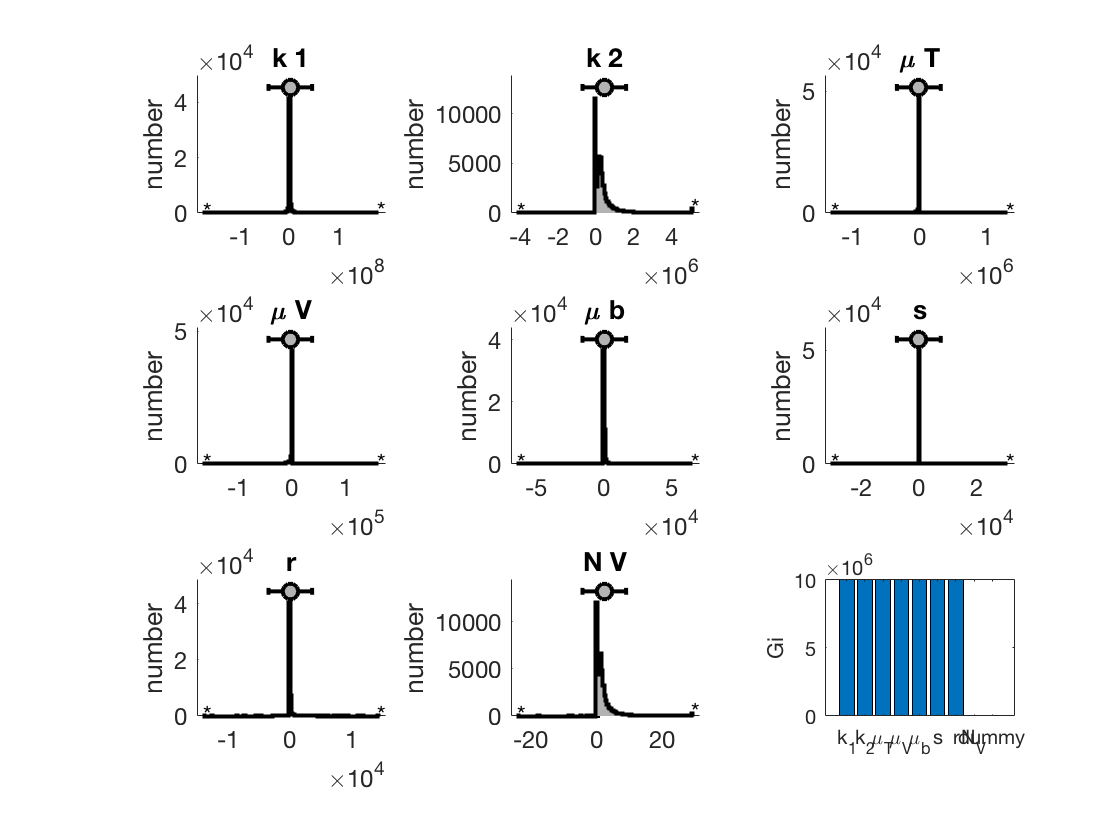

subplot(3,3,9)
bar(Gi(id))
ylim([0,1e7])
xticks([1:k]); 
xticklabels(Parameter_var(id))
ylabel('Gi')
set(gca, 'FontSize',10)

table(Parameter_var(id), Gi(id)','VariableNames',{'Parameter','Gi'})

ans = 9×2 table
    Parameter        Gi    
    _________    __________

     'k_1'       1.9731e+15
     'k_2'       1.5312e+12
     '\mu_T'     1.0636e+11
     '\mu_V'     1.6542e+09
     '\mu_b'     2.6003e+08
     's'         5.7583e+07
     'r'          1.232e+07
     'N_V'           50.111
     'dummy'              0


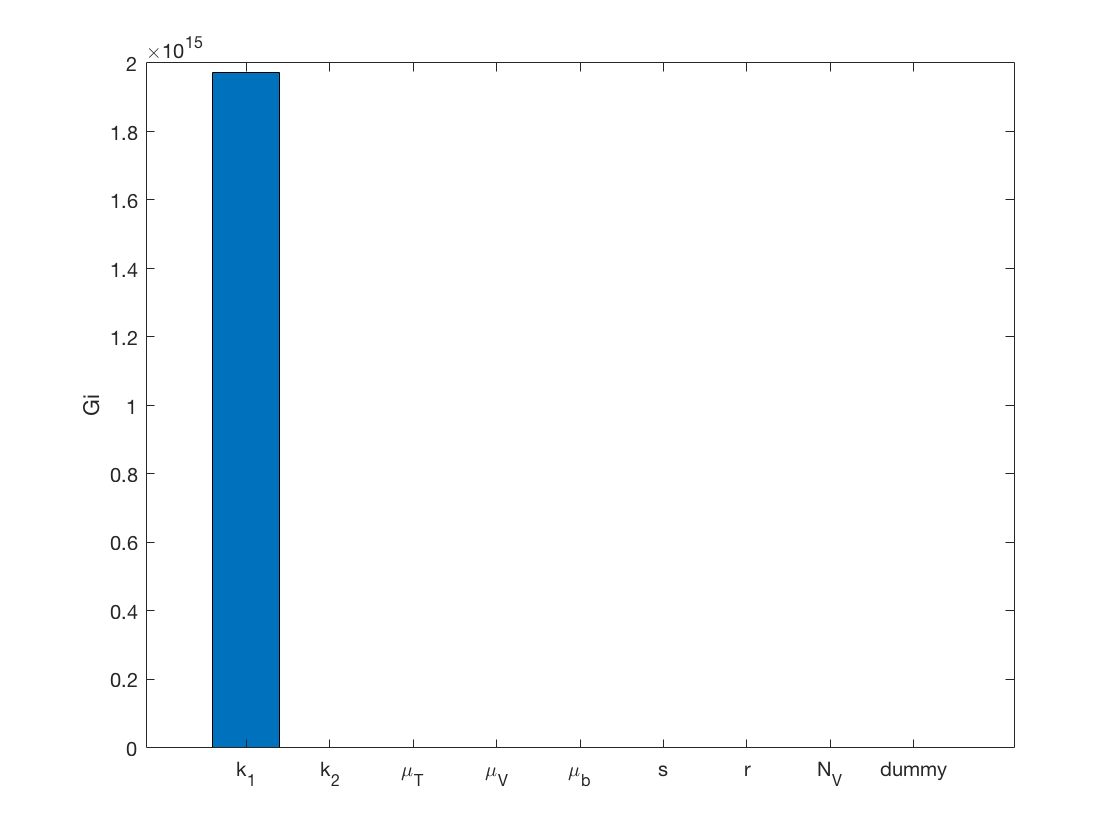

figure
bar(Gi(id))
xticks([1:k]); 
xticklabels(Parameter_var(id))
ylabel('Gi')
set(gca, 'FontSize',10)

We will use ratio as a measure

ratio = ave_sens./std_sens;
[~,id] = sortrows(ratio','descend');

table(Parameter_var(id), ratio(id)','VariableNames',{'Parameter','Ratio'})

ans = 9×2 table
    Parameter     Ratio  
    _________    ________

     'dummy'          NaN
     'k_2'        0.40094
     'N_V'        0.35711
     '\mu_V'      0.10292
     'k_1'       0.072609
     '\mu_T'      0.05096
     '\mu_b'     0.028083
     'r'         0.027877
     's'         0.014129


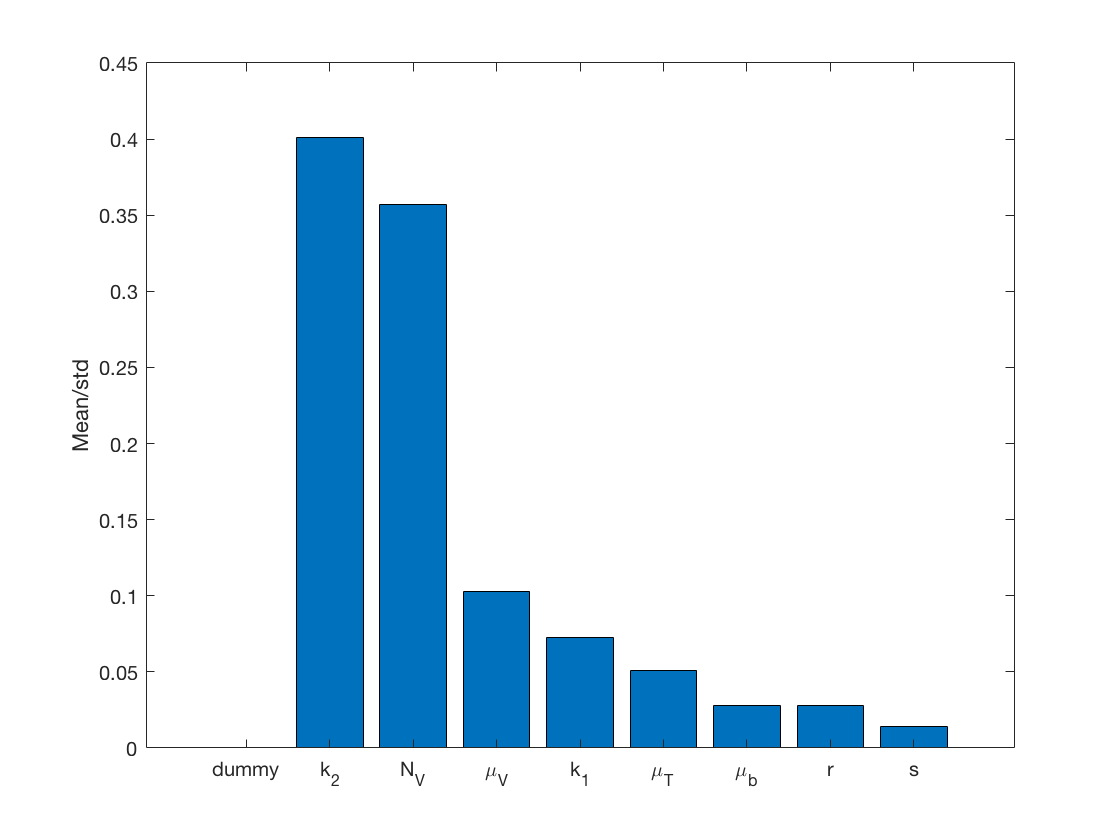



figure
bar(ratio(id))
xticks([1:k]); 
xticklabels(Parameter_var(id))
ylabel('Mean/std')
set(gca, 'FontSize',10)